# **demo08 of writeMesh**

**Hexahedral mesh**

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/writeMesh).

## Initialize

clearvars

Set default image size.

x = 250; y = 250; width = 350; height = 350;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Load mesh

Let's load the mesh data from "mesh_data_5.mat"

load("mesh_data_5.mat")

We will see 3 variables: vert, ele, tnum

vert

vert =     0.5000    0.5000    0.5000
    0.5000    1.5000    0.5000
    0.5000    2.5000    0.5000
    0.5000    3.5000    0.5000
    1.5000    0.5000    0.5000
    1.5000    1.5000    0.5000
    1.5000    2.5000    0.5000
    1.5000    3.5000    0.5000
    2.5000    0.5000    0.5000
    2.5000    1.5000    0.5000


ele

ele =      1     5     6     2    37    41    42    38
     2     6     7     3    38    42    43    39
     3     7     8     4    39    43    44    40
     5     9    10     6    41    45    46    42
     6    10    11     7    42    46    47    43
     7    11    12     8    43    47    48    44
    37    41    42    38    73    77    78    74
    38    42    43    39    74    78    79    75
    39    43    44    40    75    79    80    76
    41    45    46    42    77    81    82    78


tnum

tnum =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


ele has 8 columns, so it's a linear hexahedral mesh.

Check the number of phase in the mesh

length(unique(tnum))

ans = 3

## Plot mesh

Use function plotMeshes3d to plot 3d mesh.

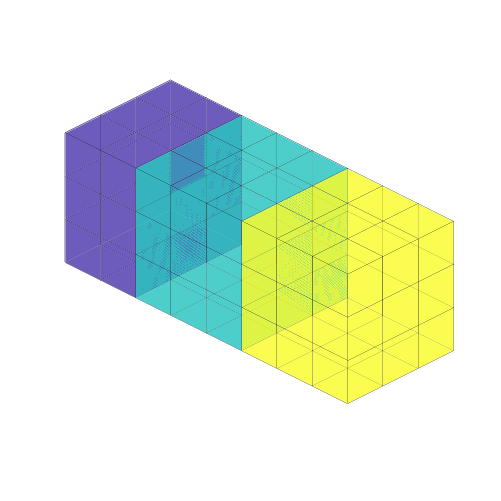

color_code = 2;
opt = [];
opt.faceAlpha = 0.5;
opt.edgeAlpha = 0.3;

plotMeshes3d( vert, ele, tnum, color_code, opt );

We saw 3 phases in the mesh.

## Linear elements

### Display boundary node set

By default, function printInp3d will automatically search and export node sets at the boundary and at the interface of 3d mesh. Before running function printInp3d, we can use function displayBCNode3d to check whether those boundary nodes have been found correctly. Please refer to demo09 for more information.

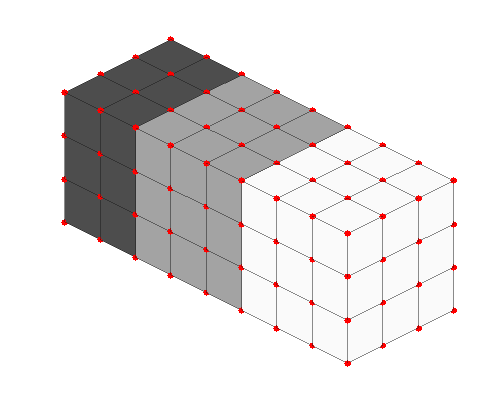

tolerance = 1E-10;
markerSize = 10;
plane = 'all';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

### Export as inp file (Abaqus)

We use function printInp3d to write 3d mesh to inp file. Please refer to demo06 to learn about format setting of inp file.

When using function printInp3d, we can specify element type, precision and file name.

ele_type = 'C3D8';
precision = 8;
file_name = 'test_linear.inp';

printInp3d( vert, ele, tnum, ele_type, precision, file_name );

printInp3d Done! Check the inp file!


### Export as bdf file (Nastran bulk data)

We use function printBdf3d to write 3d mesh to bdf file.

precision = 8;
file_name = 'test.bdf';

printBdf3d( vert, ele, tnum, [], precision, file_name );

printBdf3d Done! Check the bdf file!


## Quadratic elements

### Convert linear elements to quadratic elements

We use function insertNode3d to convert the linear 3d elements to quadratic 3d elements. Function insertNode3d works for tetrahedral and hexahedral mesh.

% vert2, ele2 define quadratic elements
[vert2, ele2] = insertNode3d(vert, ele);

### Display boundary node set

Before running function printInp3d, we can use function displayBCNode3d to check whether those boundary nodes have been found correctly. Please refer to demo09 for more information.

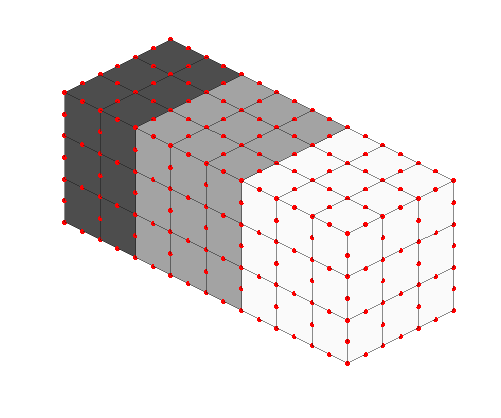

tolerance = 1E-10;
markerSize = 8;
plane = 'all';
displayBCNode3d( vert2, ele2, tnum, tolerance, markerSize, plane );

### Export as inp file (Abaqus)

We use function printInp3d to write 3d mesh to inp file. 

ele_type = 'C3D20';
precision = 8;
file_name = 'test_quadratic.inp';

printInp3d( vert2, ele2, tnum, ele_type, precision, file_name );

printInp3d Done! Check the inp file!


% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo